# Groundwater recharge between two rivers

set_demo_defaults();

Consider the following problem taken from Sanford et al. (2001) and shown below. The Danube-Tisza Interfluve is a large agricultural area in Hungary between two the Danube and the Tisza rivers. The mean elevation of the Danube in the area is approximately 90 m and the mean elevation of the Tisza in the area is apporximately 80 m above sea level. The region recieves an average of 1.5 cm/yr of precipitation and the underlying aquifer is approximately 100 m thick with a hydraulic conductivity of approximately $2\times10^{-2}$ cm/s.

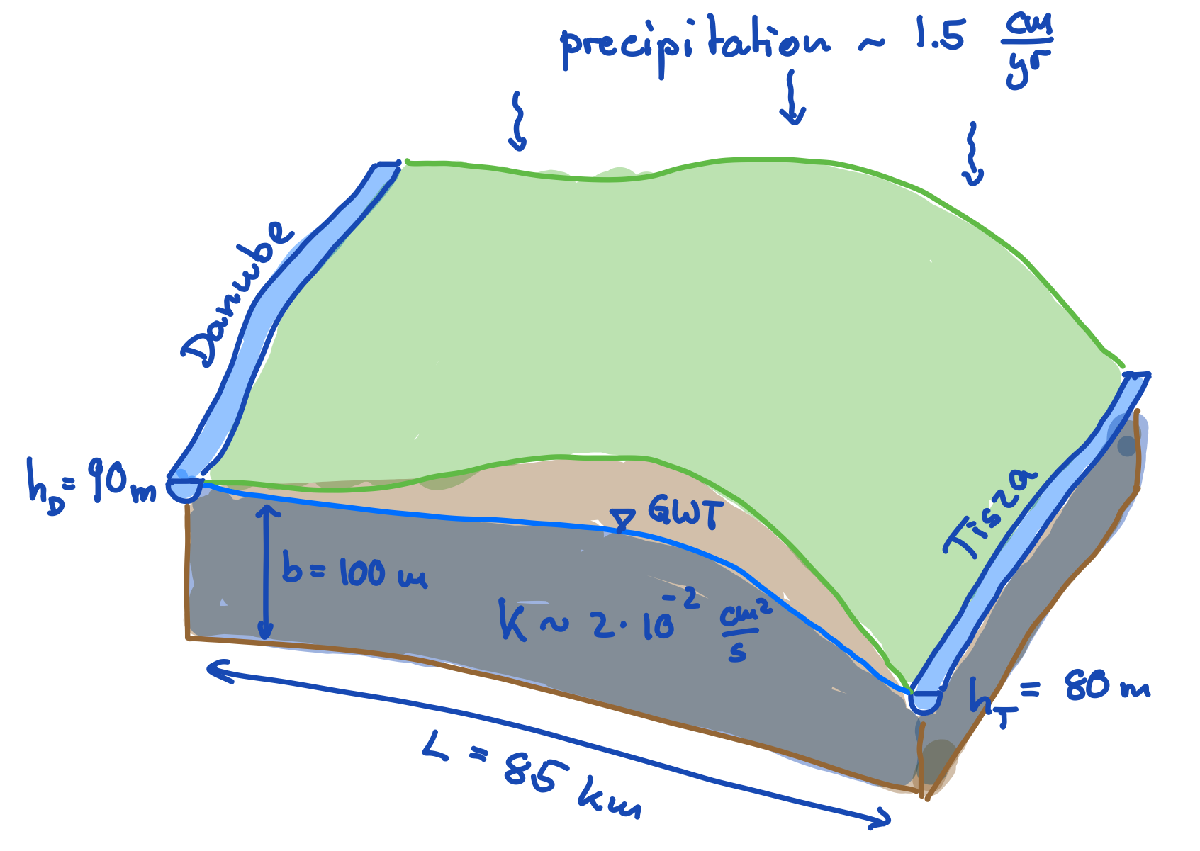

%% Physical properties
cm2m = 1/100;        % cm to m conversion
yr2s = 365*24*60^2;  % yr to s conversion

Length = 85070;      % Distance between Danube and Tisza rivers [m]
Width = 5430;        % Width of segment considered [m]
K =2e-2*cm2m;        % Hydraulic conductivity [m/s]
qp = 1.5*cm2m/yr2s;  % Average annual precipitation [m3/m2/s]
hD = 90;             % Elevation of Danube river[m]
hT = 80;             % Elevation of Tisza river [m]
b = 100;             % Aquifer thickness [m]

The area is popuar for hydrological studies because the rivers run parallel for more than 100 km (see map) with very little change in elevation. This setup a geometry that can be approximated by a two-dimensional cross-section.

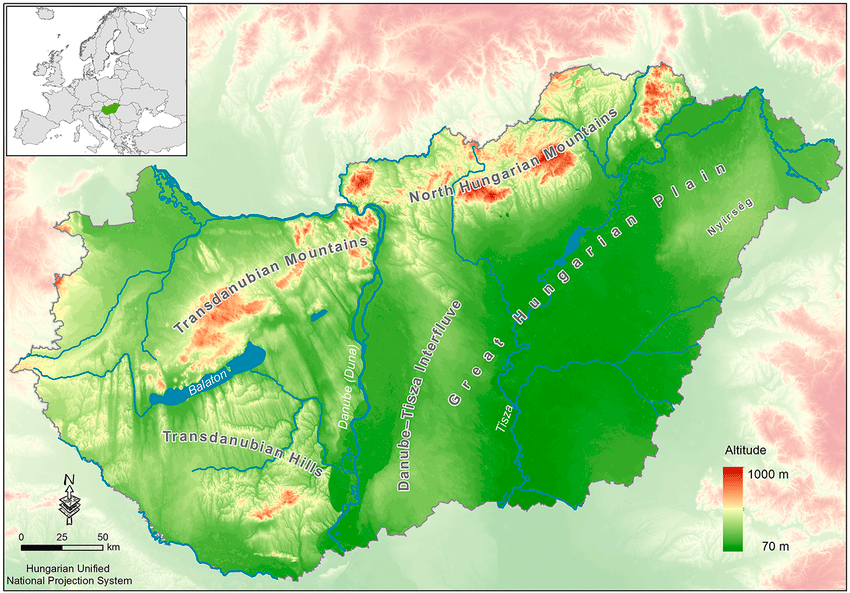

#### Shallow aquifer model

We further simplify the model by introducing a shallow aquifer approximation because the large aspect ratio of cross section, $b/H = 1/850\approx10^{-3}$. In this limit the flow is horizontal to first-order and we can integrate the the governing equation as follows


$$\int_0^{b(x)}\nabla\cdot \mathbf{q} \,\mathrm{d}z = \nabla\cdot \int_0^{b(x)}\mathbf{q} \,\mathrm{d}z + \left.\mathbf{q}\cdot\hat{\mathbf{n}}_\mathrm{bot}\right|_{z=b(x)}-\left.\mathbf{q}\cdot\hat{\mathbf{n}}_\mathrm{top}\right|_{z=0}$$


Making the following assumptions

- The flux is horizontal: $\mathbf{q} = [q_x\,\,0]^T$ and $q_x = -K \frac{\mathrm{d}h}{\mathrm{d}x}$, where pressure is hydrostatic so that $h = h(x)$

- The base of the aquifer is impermable: $\left.\mathbf{q}\cdot\hat{\mathbf{n}}_\mathrm{bot}\right|_{z=b(x)} =0$

- Slope of the top of the aquifer is negligible: $\left.\mathbf{q}\cdot\hat{\mathbf{n}}_\mathrm{top}\right|_{z=0} = -q_p$

We obtain the shallow aquifer model for the interfluve:

PDE:  $-\tilde{\nabla}\cdot\left[b\,K \tilde{\nabla} h\right] = q_r$ on $x \in \left[0,\, L\right]$

BC:    $h(0)=h_\mathrm{D} = 90$m   and  $h(x=L)=h_\mathrm{T} = 80$ m

Here the tilde on the divergence and gradient operators indicates that they only contain horizontal derivatives, because we have integrated in the vertical.

In 1D the PDE can also simply be written as


$$-\frac{\mathrm{d}}{\mathrm{d}x}\left[b\,K\frac{\mathrm{d}h}{\mathrm{d}x}\right]=q_p$$


and solved by integrating twice to obtain the following solutions for the head $h$ and flux $q$


$$h = h_D+\left(\frac{q_pL}{2bK}-\frac{h_D-h_T}{L}\right)x-\frac{q_p}{2bK}x^2$$



$$q=\frac{q_p}{b}\left(x-\frac{L}{2}\right)+\frac{K}{L}\left(h_D-h_T\right)$$


% Analytic solution
xa = linspace(0,Length,1e2);
ha = @(x,qr) hD + (qr*Length/2/b/K-(hD-hT)/Length)*x - qr/2/b/K*x.^2;
qa = @(x,qr) qr/b*(x-Length/2) + K/Length*(hD-hT);

#### Critical recharge to create a groundwater divide

In the absence of recharge water flows down the hydraulic gradient from the Danube towards the Tisza river and the head varies linearly. As recharge/precipitation increases the head is curved downwards and eventually a maximum forms that divides the intefluve into a region that flow into the Danume and another that flows into the Tisza river.

The location of the groundwater divide is obtained by setting $q=0$ and solving for $x$ to obtain


$$x_\mathrm{max} = \frac{2}{L}+\frac{Kb(h_D-h_T)}{q_pL} $$


and the critical recharge is given when $x_\mathrm{max} = 0$ so that


$$q_\mathrm{p,crit}=\frac{2Kb(h_D-h_T)}{L^2}$$


xmax = @(qr) Length/2 - (K*b*(hD-hT))/(qr*Length);
qp_crit = 2*K*b*(hD-hT)/Length^2

qp_crit = 5.5272e-11

The model is shown below for increasing recharge/precipitation.

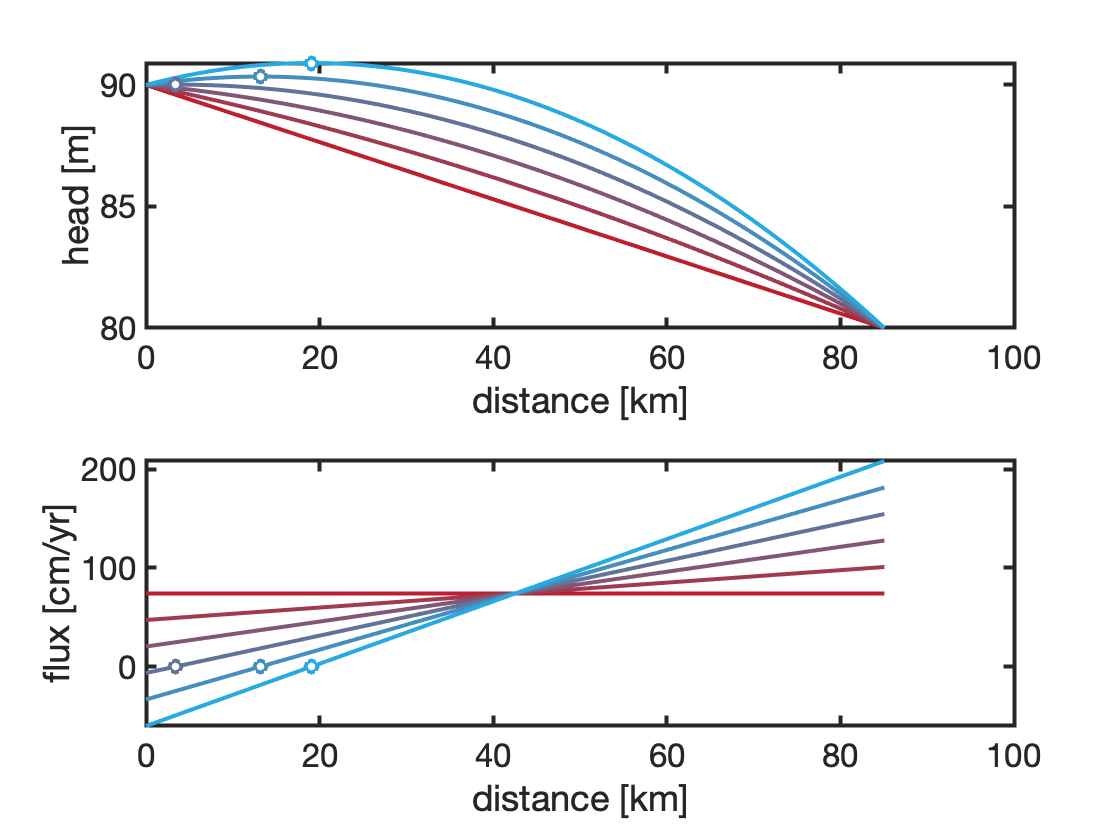

col = marc_colors();
% create custom color map
N = 6;
RED = repmat(col.red,N,1);
BLUE = repmat(col.blue,N,1);
ALPHA = repmat(linspace(0,1,N)',1,3);
COL = BLUE.*ALPHA + RED.*(1-ALPHA);

clf
subplot 211
plot(xa/1e3,ha(xa,0e-11),'-','color',COL(1,:)), hold on
plot(xa/1e3,ha(xa,2e-11),'-','color',COL(2,:))
plot(xa/1e3,ha(xa,4e-11),'-','color',COL(3,:))
plot(xa/1e3,ha(xa,6e-11),'-','color',COL(4,:))
plot(xa/1e3,ha(xa,8e-11),'-','color',COL(5,:))
plot(xa/1e3,ha(xa,1e-10),'-','color',COL(6,:))
plot(xmax(6e-11)/1e3,ha(xmax(6e-11),6e-11),'o','markeredgecolor',COL(4,:),'markerfacecolor','w','markersize',6)
plot(xmax(8e-11)/1e3,ha(xmax(8e-11),8e-11),'o','markeredgecolor',COL(5,:),'markerfacecolor','w','markersize',6)
plot(xmax(1e-10)/1e3,ha(xmax(1e-10),1e-10),'o','markeredgecolor',COL(6,:),'markerfacecolor','w','markersize',6)
xlabel 'distance [km]'
ylabel 'head [m]'

subplot 212
plot(xa/1e3,qa(xa,0e-11)/(cm2m/yr2s),'-','color',COL(1,:)), hold on
plot(xa/1e3,qa(xa,2e-11)/(cm2m/yr2s),'-','color',COL(2,:))
plot(xa/1e3,qa(xa,4e-11)/(cm2m/yr2s),'-','color',COL(3,:))
plot(xa/1e3,qa(xa,6e-11)/(cm2m/yr2s),'-','color',COL(4,:))
plot(xa/1e3,qa(xa,8e-11)/(cm2m/yr2s),'-','color',COL(5,:))
plot(xa/1e3,qa(xa,1e-10)/(cm2m/yr2s),'-','color',COL(6,:))
plot(xmax(6e-11)/1e3,0,'o','markeredgecolor',COL(4,:),'markerfacecolor','w','markersize',6)
plot(xmax(8e-11)/1e3,0,'o','markeredgecolor',COL(5,:),'markerfacecolor','w','markersize',6)
plot(xmax(1e-10)/1e3,0,'o','markeredgecolor',COL(6,:),'markerfacecolor','w','markersize',6)
xlabel 'distance [km]'
ylabel 'flux [cm/yr]'